clear
load SYS
load C %compensator designed is saved as C
[A,B,C1,D] = ssdata(SYS)

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067    0.0267


B =          0
         0
    0.6667
    0.6667


C1 =      0     1     0     0


D = 0

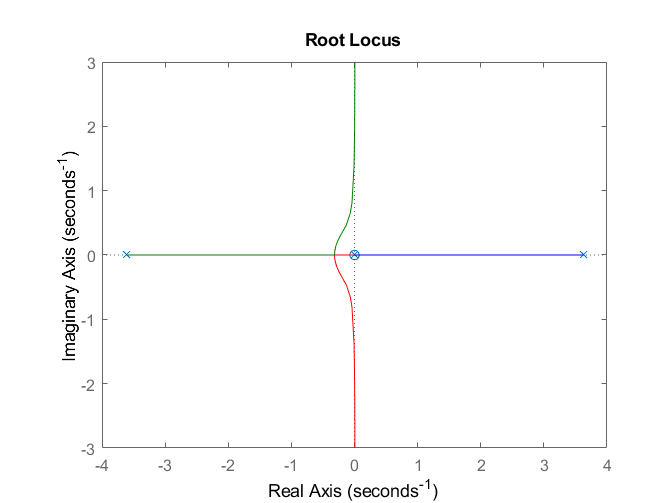

rlocus(SYS)

The root locus remains the same if we use P-controller. So, even after using P-controller we are going to have roots on the right half of the plane which makes the system unstable

Gs = tf(SYS)

Gs =
 
         0.6667 s + 2.891e-19
  ----------------------------------
  s^3 - 0.02 s^2 - 13.09 s - 0.06547
 
Continuous-time transfer function.



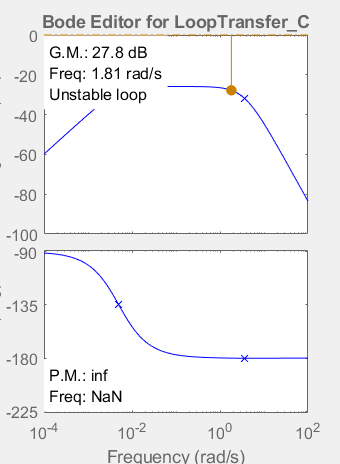

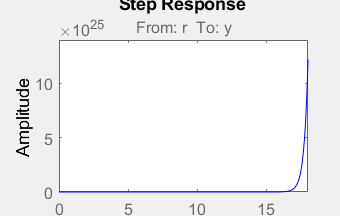

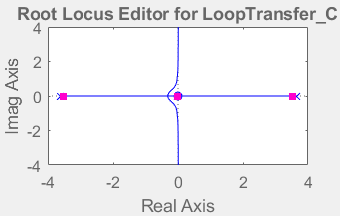

sisotool(Gs)

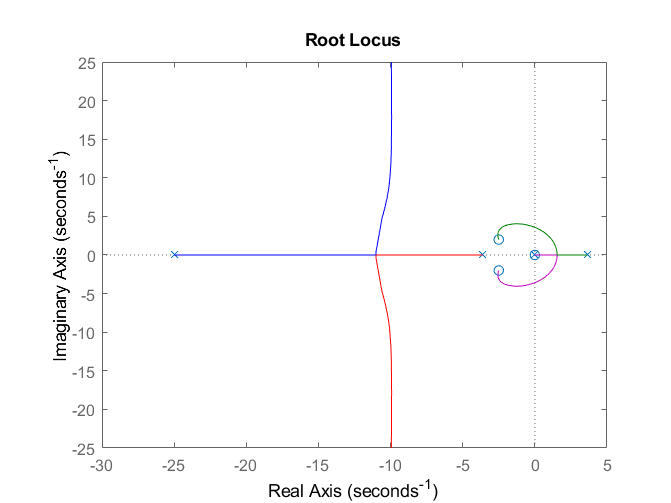

rlocus(SYS*C) % Root locus after using compensator

Cs = tf(C)

Cs =
 
  1898 s^2 + 9489 s + 1.945e04
  ----------------------------
           s^2 + 25 s
 
Name: C
Continuous-time transfer function.

